# Exercise 1

hours = 1:7;
temps = [13 15 20 14 15 13 10];

X = [hours' ones(length(hours),1)];
params = X \ temps';
slope = params(1);
intercept = params(2);

predicted_temp8 = slope * 8 + intercept;
fprintf('Temperature estimated at 8: %.2f °C\n', predicted_temp8);

Temperature estimated at 8: 11.71 °C


fit_line = slope * hours + intercept;
total_error = sum((temps - fit_line).^2);
fprintf('The error E = %.4f\n', total_error);

The error E = 43.8571


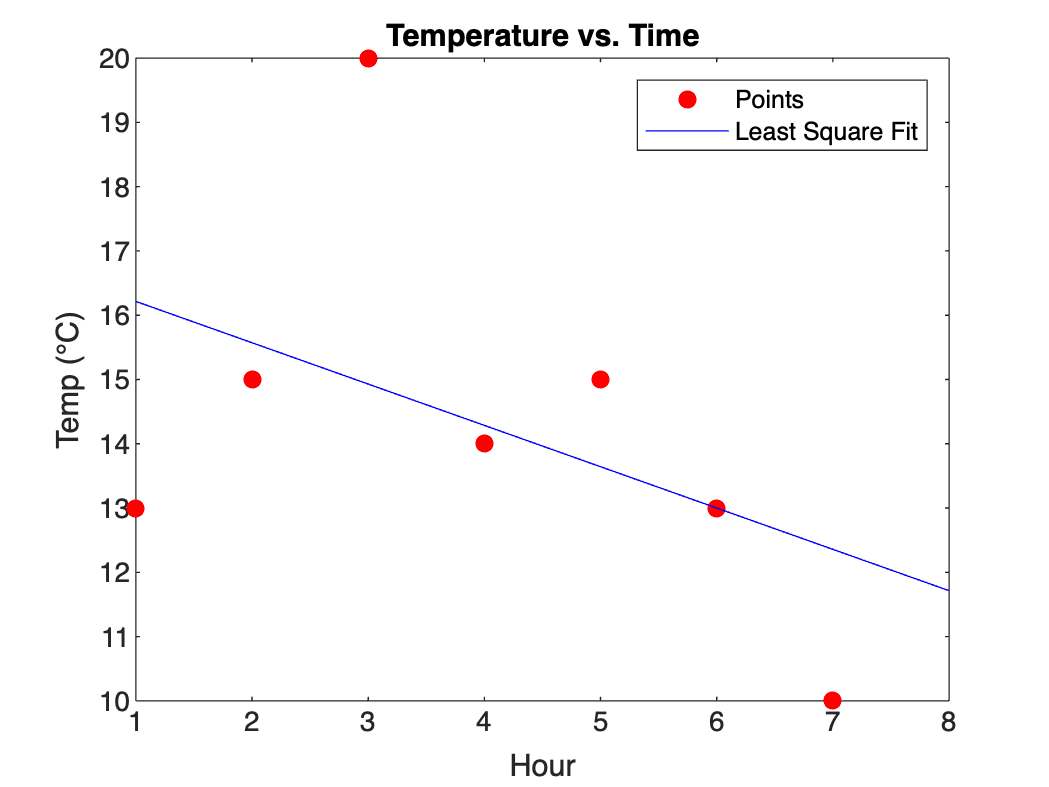

figure;
plot(hours, temps, 'ro', 'MarkerFaceColor', 'r'); hold on;
plot(1:8, slope * (1:8) + intercept, 'b-');
xlabel('Hour');
ylabel('Temp (°C)');
legend('Points', 'Least Square Fit');
title('Temperature vs. Time');

## Exercise 2

temps_c = [0 10 20 30 40 60 80 100];
pressures = [0.0061 0.0123 0.0234 0.0424 0.0738 0.1992 0.4736 1.0133];

poly_deg2 = polyfit(temps_c, pressures, 2);
poly_deg3 = polyfit(temps_c, pressures, 3);

estimate_deg2 = polyval(poly_deg2, 45);
estimate_deg3 = polyval(poly_deg3, 45);
actual_value = 0.095848;

err_deg2 = abs(estimate_deg2 - actual_value);
err_deg3 = abs(estimate_deg3 - actual_value);

fprintf('Poly Deg 2 at T = 45: %.5f (Error: %.5f)\n', estimate_deg2, err_deg2);

Poly Deg 2 at T = 45: 0.08578 (Error: 0.01007)


fprintf('Poly Deg 3 at T = 45: %.5f (Error: %.5f)\n', estimate_deg3, err_deg3);

Poly Deg 3 at T = 45: 0.08813 (Error: 0.00771)


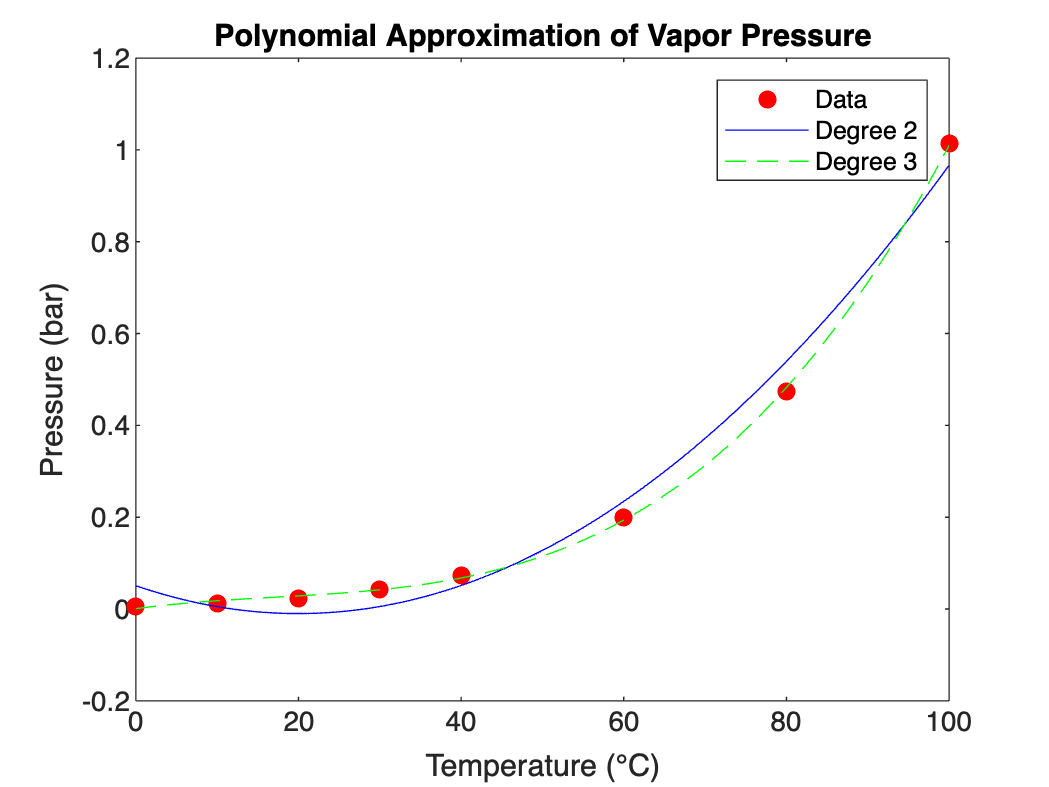

figure;
plot(temps_c, pressures, 'ro', 'MarkerFaceColor', 'r'); hold on;
T_fine = linspace(0, 100, 200);
plot(T_fine, polyval(poly_deg2, T_fine), 'b-', 'DisplayName', 'Deg 2');
plot(T_fine, polyval(poly_deg3, T_fine), 'g--', 'DisplayName', 'Deg 3');
xlabel('Temperature (°C)');
ylabel('Pressure (bar)');
legend('Data', 'Degree 2', 'Degree 3');
title('Polynomial Approximation of Vapor Pressure');

## Exercise 3

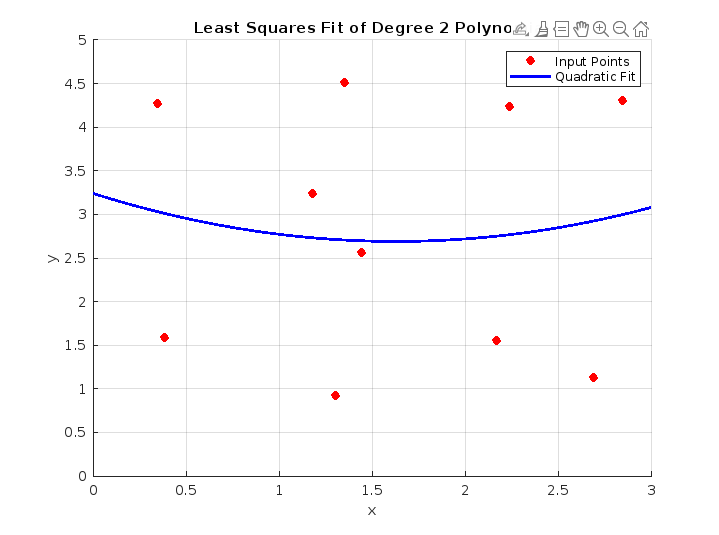

figure;
axis([0 3 0 5]);
xlabel('x'); ylabel('y');
title('Select 10 random points in [0,3] × [0,5]');
grid on;

[x_clicks, y_clicks] = ginput(10);
coeffs_quad = polyfit(x_clicks, y_clicks, 2);

hold on;
plot(x_clicks, y_clicks, 'ro', 'MarkerFaceColor', 'r');
x_curve = linspace(0, 3, 200);
plot(x_curve, polyval(coeffs_quad, x_curve), 'b-', 'LineWidth', 2);
legend('Input Points', 'Quadratic Fit');
title('Least Squares Fit of Degree 2 Polynomial');